# The construction of 2D and 3D curve and different approaches to solve Distance Geometry problem.

Author: Viet Hoang Do, Yang Ziying

## Abstract

In this paper, we study the construction of the Hilbert curve 2D and 3D. We propose different methods to reconstruct the Hilbert curve such as using singular value decomposition (SVD), using Schur decomposition, and using linear least-squares to solve geometric buildup problems. We also investigate how the noise in the distance matrix can affect the reconstruction process.

## Introduction

The Hilbert curve is a space-filling curve that is generated recursively, like other fractals.  It is a continuous path that passes through each point in a 2D space exactly once and never crosses itself.  The most well-known property of the Hilbert curve is locality preserving - which enables the wide use of the Hilbert Curve in computer science applications. This paper introduces the recursive algorithm to generate coordinates of the n-th order Hilbert curve in 2D and 3D space. It also studies the reconstruction of the curve and discusses the output result produced by three approaches.

## Method

### Construct the 2D Hilbert Curve

In the first iteration, the step to construct the Hilbert curve is dividing the square region into 4 sub-regions, then connect the points at the centers of the 4 sub-region by an upside-down square 'U'. For the next iteration, each of the 4 sub-regions is divided into 4 smaller sub-regions. The top-left region contains the duplicate figure of the last iteration. The bottom-left region contains the rotated-90-degree-clockwise duplicated figure of the last iteration. The right region is the fliped figure of the left region. The below is the function that implements a recursive algorithm to construct a 2D Hilbert curve:

% function [x,y] = hilbert(n)
% %HILBERT Hilbert curve.
% %
% % [x,y]=hilbert(n) gives the vector coordinates of points
% %   in n-th order Hilbert curve of area 1.
% if n<=0
%   x=0;
%   y=0;
% else
%   [xo,yo]=hilbert(n-1);
%   x=.5*[-.5+yo -.5+xo .5+xo  .5-yo];
%   y=.5*[-.5+xo  .5+yo .5+yo -.5-xo];
% end

The function 'hilbert_length' is used to compute the sum of the distance between two consecutive points in the set of coordinates retrieved by 'hilbert' function.

% function d = hilbert_length(n)
% %hilbert_length Calcaulate the length of n-th order curve
% 
% [x , y] = hilbert(n);
% d = 0;
% for n = 1:length(x)-1
%     d = d + distance(x(n),y(n),x(n+1),y(n+1));    
% end
% end

We also calculate the total number of turning points from the set of coordinates returned by the 'hilbert' function. A point is considered as a turning point if it along with the previous and next points are not in the same line. 

% function p = hilbert_points(n)
% % hilbert_points Calculate total number of points in n-th order Hilbert Curve
%
% [x, y] = hilbert(n);
% p = 2; %start and end points
% for n = 2:length(x)-1
%     if ~((x(n) == x(n-1) && x(n) == x(n+1))  || (y(n) == y(n-1) && y(n)== y(n+1))) 
%         p = p + 1;
%     end
% end
% end

After identifying which points are turning points, we can construct the distance matrix for all the above turning points. The distance matrix is a square N x N matrix for N equals the number of turning points. The diagonal of distance matrix contains only 0s since the distance between a point and itself is 0.

% function A = distance_matrix_hilbert(n, dim)
% % distance_matrix Distance matrix of all turning points
% 
% if (dim == 2) % distance matrix for 2D Hilbert Curve
%     [x, y] = hilbert(n);
%     x_temp = x(1);
%     y_temp = y(1);
% 
% 
%     for n = 2:length(x)-1
%         if ~((x(n) == x(n-1) && x(n) == x(n+1))  || (y(n) == y(n-1) && y(n)== y(n+1))) 
%             x_temp = [x_temp, x(n)];
%             y_temp = [y_temp, y(n)];
%         end
%     end
% 
%     x_temp = [x_temp, x(length(x))];
%     y_temp = [y_temp, y(length(x))];
% 
%     A = [x_temp;y_temp];
%     A = squareform(pdist(A'));
%     
% elseif (dim == 3) % distance matrix for 3D Hilbert Curve
%     [x, y, z] = hilbert3(n);
%     x_temp = x(1);
%     y_temp = y(1);
%     z_temp = z(1);
% 
% 
%     for n = 2:length(x)-1
%         if (x(n) == x(n-1) && x(n) == x(n+1))  + (y(n) == y(n-1) && y(n)== y(n+1)) + (z(n) == z(n-1) && z(n)== z(n+1)) < 2 
%             x_temp = [x_temp, x(n)];
%             y_temp = [y_temp, y(n)];
%             z_temp = [z_temp, z(n)];
%         end
%     end
% 
%     x_temp = [x_temp, x(length(x))];
%     y_temp = [y_temp, y(length(x))];
%     z_temp = [z_temp, z(length(x))];
% 
%     A = [x_temp;y_temp;z_temp];
%     A = squareform(pdist(A')); 
% end   
% end

We try to reconstruct the 4 x 4 distance matrix using the basic geometric properties of the curve.

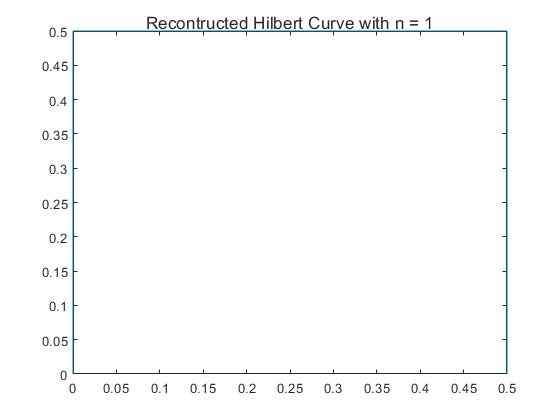

d = distance_matrix_hilbert(1, 2);

% Get distance of consecutive turning points
path = diag(d, 1);

% Find the first point
x = zeros(1, length(path) + 1);
y = zeros(1, length(path) + 1);

x(1) = 0;
y(1) = 0;

sign_array = [1 1 -1];

for i=1:length(path)    	       
    if (mod(i, 2) == 0)
        x(i + 1) = x(i) + sign_array(i) * path(i);
        y(i + 1) = y(i);
    else
        x(i + 1) = x(i) ;
        y(i + 1) = y(i) + sign_array(i) * path(i);
    end  	    	
end

figure;
t = tiledlayout(1, 1);
title(t, "Recontructed Hilbert Curve with n = 1");
plot(x, y)

### Construct the 3D Hilbert Curve

In the first iteration, the step to construct the 3D Hilbert curve is dividing the square space into 8 sub-spaces, then connect the points at the centers of the 8 sub-space by the pattern below: 

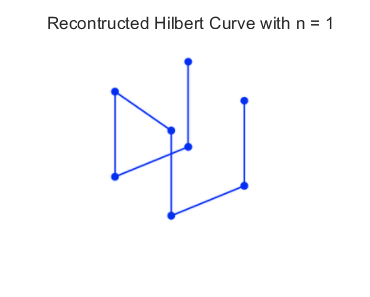

imshow('hilbert_3d_pattern.png');

For the next iteration, each of the 8 sub-space is divided into 8 smaller sub-spaces. Each group of 4 smaller sub-spaces contain the rotated duplicated figure of the last iteration.  The 4 sub-spaces in the left form a figure that is the flipped one of the 4 sub-spaces in the right. The below is the code that implements a recursive algorithm to construct a 3D Hilbert curve:

% function [x,y, z] = hilbert3(n)
% %HILBERT Hilbert curve 3D.
% %
% % [x,y, z]=hilbert3(n) gives the vector coordinates of points
% %   in n-th order Hilbert curve of area 1.
% 
% if nargin ~= 1
%     n = 2;
% end
% if n <= 0
%     x = 0;
%     y = 0;
%     z = 0;
% else
%     [xo,yo,zo] = hilbert3(n-1);
%     x = .5*[.5+zo .5+yo -.5+yo -.5-xo -.5-xo -.5-yo .5-yo .5+zo];
%     y = .5*[.5+xo .5+zo .5+zo .5+yo -.5+yo -.5-zo -.5-zo -.5-xo];
%     z = .5*[.5+yo -.5+xo -.5+xo .5-zo .5-zo -.5+xo -.5+xo .5-yo];
% end

### Reconstruction sets of vertices

#### SVD approach

Given the distance matrix A with the size of n x n. We compute the matrix M such that M(i, j) = (A(i, n) ^ 2 - A(i, j) ^ 2 + A(j, n) ^ 2)/2. Using 'svd' function to perform a singular value decomposition of matrix M such that M = U * S * V`. Then we compute X = U * sqrt(S). We assume that the matrix S has R non-zero singular values. We need to take from X the R columns corresponding to non-singular values in S. That would be our result. The algorithm for the 'svd' approach is shown below:

% function X = svd_reconstruct(d)
%     
% % Length of  distance matrix
% n = length(d);
% 
% % Calculate M = X * transpose(X)
% % M = (m(i,j) for i,j = 1, ... n-1))
% M = zeros(n, n);
% 
% % SVD method to reconstruct coordinates
% for i = 1:n
%     for j = 1:n
%         M(i, j) = (d(i, n) ^ 2 - d(i, j) ^ 2 + d(j, n) ^ 2)/2;
%     end
% end
% 
% [U, S, V] = svd(M);
% index = find(diag(S) > 0.000001);
% X = U * sqrt(S);
% empty = [];
% 
% for i = 1:length(index)
%     empty =[empty X(:, index(i))];
% end
% X = empty;
% end

#### Schur approach

Given the distance matrix A with the size of n x n. We compute the matrix M such that M(i, j) = (A(i, n) ^ 2 - A(i, j) ^ 2 + A(j, n) ^ 2)/2. Using the 'schur' function to compute the Schur form T of the matrix M and a unitary matrix Q such that M = Q * T * Q'. Then we compute  X = Q * sqrt(T). We assume that the matrix T has R non-zero singular values. We need to take from X the R columns corresponding to non-singular values in T. That would be our result. The algorithm for the 'schur' approach is shown below:

% function X = schur_reconstruct(d)
%     
% % Length of  distance matrix
% n = length(d);
% 
% % Calculate M = X * transpose(X)
% % M = (m(i,j) for i,j = 1, ... n-1))
% M = zeros(n, n);
% 
% % Schur method to reconstruct coordinates
% for i = 1:n
%     for j = 1:n
%         M(i, j) = (d(i, n) ^ 2 - d(i, j) ^ 2 + d(j, n) ^ 2)/2;
%     end
% end
% 
% [Q, T] = schur(M);
% X = Q * sqrt(T);
% index = find(diag(T) > 0.001);
% empty = [];
% 
% for i = 1:length(index)
%     empty =[empty X(:, index(i))];
% end
% X = empty;
% end

Using two proposed methos, we compute the distance matrix for three sample sets of vertices. Then we solve the distance matrix to retrieve the set of vertices that represents the reconstructed curve.

### **Reconstruction of 2D and 3D Hilbert**

In this part, we are using the SVD and Schur method to reconstruct the Hilbert of n-th order. The first step is to compute the distance matrix of the Hilbert curve by the function 'distance_matrix_hilbert'. Next, we attempt to solve the distance matrix using both SVD and Schur function.

### Linear least square Build Up Algorithm

Assume we are solving Geometric Build Up problem in k dimension. The LLS Build Up Algorithm is described as below steps:

- Find k + 1 points that are not in the same plane

- Use the SVD method to calculate the coordinates of those k + 1 points with the distances among them

- Loop: For each of the undetermined points. f the point has l distances to l determined points that are not in the same plane. Determine the point with the least-squares fit to the distances.

- If no point can be determined in the loop, break

- All points are determined

We implement the LLS Build Up Algorithm to reconstruct three sample sets of vertices and the Hilbert curve. We also investigate how well the algorithm would perform in case there is noise in the data. The LLS algorithm is shown below:

% function X = build_up_LLS(d,dim)
% 
% index = (1: dim);
% point_index = find_point_dif_plane(d, dim);
% index = [index point_index];
% 
% X = zeros(length(d), dim);
% 
% d_determined = d([1:dim, index(end)], [1:dim, index(end)]);
% X([1:dim, index(end)], :) = svd_reconstruct(d_determined);
% 
% skip = index(end);
% 
% for j = dim+1:length(d)
%     % Ax = b 
%     % L x 3 * 3 x 1 = L x 1
%     if j ~= skip        
%         X = X';
%         A = [];
%         b = [];   
% 
%         for i = 1:length(index)-1
%             A = [A; -2 * transpose(X(:,index(i+1)) - X(:, index(i)))]; 
%             b = [b ; d( index(i+1), j)^2 - d(index(i), j)^2 - (norm(X(:,index(i+1))) ^ 2 - norm(X(:, index(i))) ^ 2)];
%         end
% 
%         x = inv(A' * A) * A' * b;
%         X(:, j) = x;
%         X = X';
%         index = [index j];
%     end
% end  
% end

## Result

### Generating a Hilbert Curve

The Hilbert curve is generated through the code (saved in hilbert.m as a function and hilbert_plot.m for plotting) and it is shown in the figure below. The Hilbert curve is generated in two dimensions and over four different iterations, and the plot is built successfully and meet the requirement. 

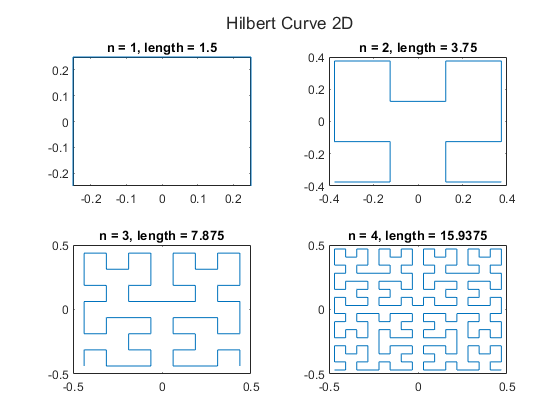

figure;
t = tiledlayout(2, 2);
title(t, "Hilbert Curve 2D");
for n = 1:4
    [X, Y] = hilbert(n);
    ax1 = nexttile;
    plot(X, Y)
    title(ax1, strcat("n = ", num2str(n), ", length = ", num2str(hilbert_length(n))));
end

The length of Hilbert Curve is shown below. Length is computed by summing up all distances in all points. When n=1(1 iteration), the Hilbert curve has a length of 1.5, and at n=2, the length increases to 3.75. As iterations increases to 3, the length of Hilbert curve is 7.875, at 4 iteration, the length of Hilbert curve is 15.9375. It is clear that when the iteration level increases, the length increases. Because within the same space, as iteration increases, there are more subdivision of same space is made, more U-shape curve are generated within each subdivision and fill the space, it curves over in a small pace and joints together. Hence, there’s more space being filled within the same region. 

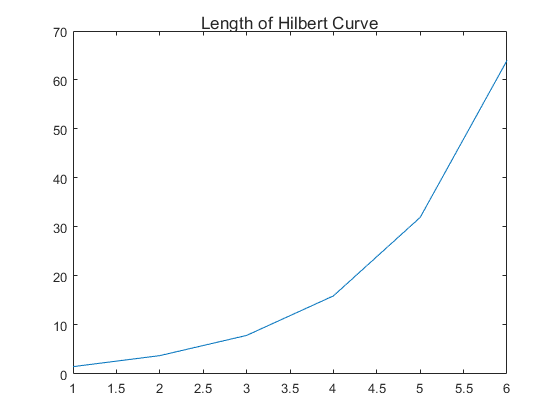

curve_length = zeros(1, 6);
for n = 1:6
    curve_length(n) = hilbert_length(n);
end

figure;
t = tiledlayout(1, 1);
title(t, "Length of Hilbert Curve");
plot((1:6), curve_length);

The total number of turning points are counted and (the code is saved in hilbert_points.m). The total number of turning points increases as the iteration level increases. As mention before, when the subdivision increases, there are more small curves needed and cause the increase of turning points. 

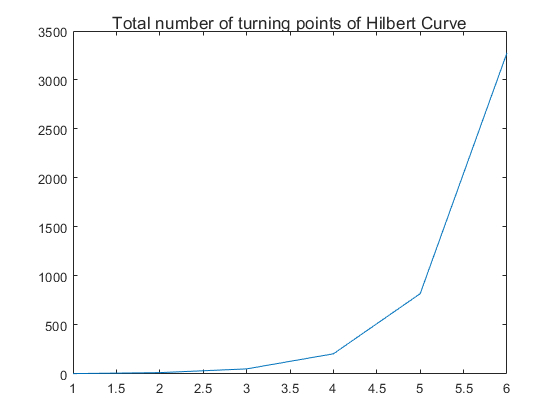

nTurning_points = zeros(1, 6);
for n = 1:6
    nTurning_points(n) = hilbert_points(n);
end

figure;
t = tiledlayout(1, 1);
title(t, "Total number of turning points of Hilbert Curve");
plot((1:6), nTurning_points);

### **Hilbert Curve and Reconstructing Curves **

#### **3D Hilbert Curve **

3D Hilbert Curve is generated in the function hilbert3.m and plotted as below. The method is being replicated and extended. Similar to 2D Hilbert Curve, 3D Hilbert curve takes three vectors as output to represent x,y,z coordinates. Not only flipping, 3D Hilbert curve also rotates to achieve conversion to the next plane. In 2D, the same pattern is being flipped and drawn into different subregion, then connect the ending point of pattern to the starting point of the next one. Similarly 3D Hilbert curve flipped and rotated the pattern then drawn in each subregion, connections are made between starting and ending points. However this connection only happens when these two points has at least one matching value in any of the axis vector. 

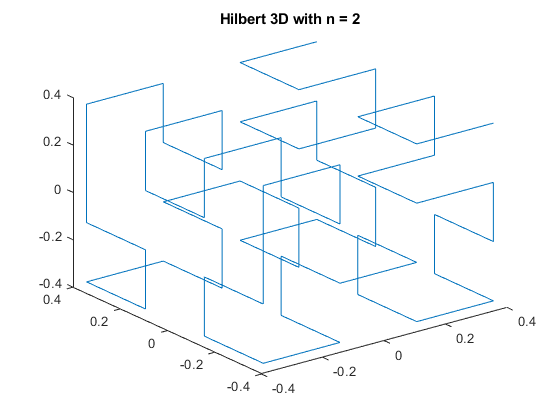

% Plot 3D curve with n = 2
[x, y, z] = hilbert3(2);
figure;
plot3(x, y, z);
title("Hilbert 3D with n = 2")

The number of turning point is counted (the code is saved in hilbert3_points.m) to be 62 turning points for n=2. 

% Number of turning points
nTurning_points = hilbert3_points(2)

nTurning_points = 62

### **Reconstructing Curve**

The sample sets of vertices

% Three sample sets
set_1 = [ -1 0; -1 1; -1/2 1/2; 0 1; 0 0];
set_2 = [ -1 0; -1 1; -1/2 1/2; 0 1; -1/4 1/4];
set_3 = [ 0 0 1; 0 1 1; -1/2 1/2 1; -1 1 1; -1 0 1; -1 0 0; -1 1 0; -1/2 1/2 0; 0 1 0; 0 0 0];

**Distance Geometry problem is solved using SVD and the result is plotted** :

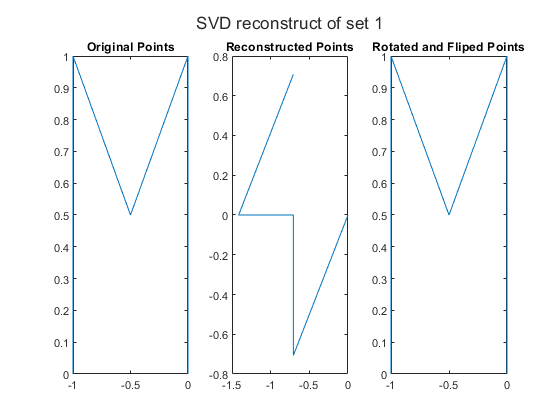

% Create rotation matrix
theta = 135; % to rotate 135 counterclockwise
R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];


% The distance matrix of set 1
d = distance_matrix(set_1);
X = svd_reconstruct(d);


% Plots
figure;
t = tiledlayout(1,3);
title(t, "SVD reconstruct of set 1");

ax1 = nexttile;
plot(set_1(:,1), set_1(:, 2));
title(ax1,'Original Points');

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Reconstructed Points');

ax3 = nexttile;
for i = 1:length(X)
    X(i,:) =  X(i,:) * R; 
    X(i, 1) = -X(i, 1); 
end
plot(X(:,1), X(:, 2));
title(ax3,'Rotated and Fliped Points');

Result is plotted and shown side by side with its original and the rotated and flipped plot. For set 1, data is given in two-dimensional, the original location is formed as a M-shape, and the rotated and flipped points return the same shape to the origin, however the SVD reconstruction returns a rotated and twisted M-shape.

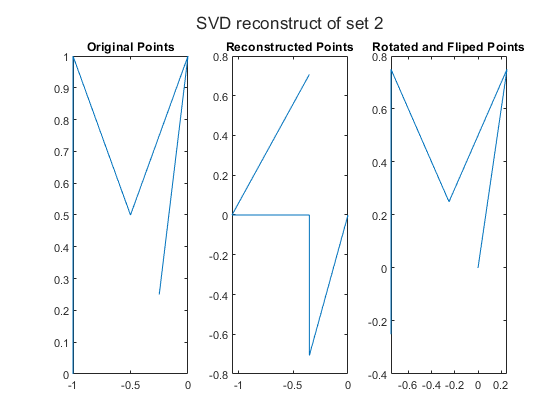


% The distance matrix of set 2
d = distance_matrix(set_2);
X = svd_reconstruct(d);

% Create rotation matrix
theta = 135; % to rotate 135 counterclockwise
R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];

% Plots
figure;
t = tiledlayout(1,3);
title(t, "SVD reconstruct of set 2");

ax1 = nexttile;
plot(set_2(:,1), set_2(:, 2));
title(ax1,'Original Points');

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Reconstructed Points');

ax3 = nexttile;
for i = 1:length(X)
    X(i,:) =  X(i,:) * R;
    X(i, 1) = -X(i, 1);    
end

plot(X(:,1), X(:, 2));
title(ax3,'Rotated and Fliped Points');

Result is plotted and shown side by side with its original and the rotated and flipped plot. For set 2, the data given is similar to set 1, the original location is formed as a M-shape with one twisted leg, and the rotated and flipped points return the same shape to the origin, however the SVD reconstruction returns a rotated and twisted M-shape that identical to the reconstructed shape in set 1.

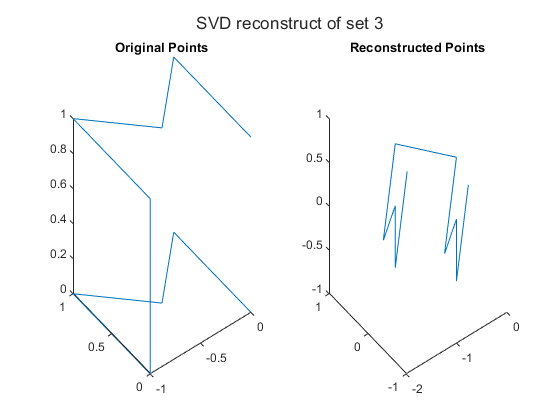

% The distance matrix of set 3
d = distance_matrix(set_3);
X = svd_reconstruct(d);

% Plots
figure;
t = tiledlayout(1,2);
title(t, "SVD reconstruct of set 3");

ax1 = nexttile;
plot3(set_3(:,1), set_3(:, 2), set_3(:,3));
title(ax1,'Original Points');

ax2 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax2,'Reconstructed Points');

Result is plotted and shown side by side with its original. For set 3, the data given is three-dimensional, the original location is formed as a shape that one M is identical to another in the different height but connected by one single line. However the SVD reconstruction returns a rotated shape that identical but shrunk. 

**Distance Geometry problem is solved using Schur and the result is plotted**

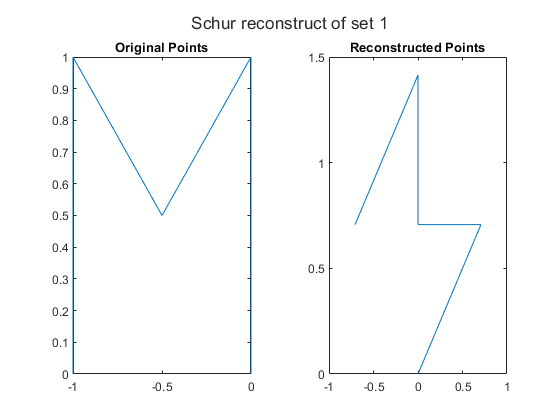

% The distance matrix of set 1
d = distance_matrix(set_1);
X = schur_reconstruct(d);

% Plots
figure;
t = tiledlayout(1,2);
title(t, "Schur reconstruct of set 1");

ax1 = nexttile;
plot(set_1(:,1), set_1(:, 2));
title(ax1,'Original Points');

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Reconstructed Points');

Result is plotted and shown side by side with its original. For set 1, data is given in two-dimensional, the original location is formed as a M-shape, however the Schur reconstruction returns a rotated and twisted M-shape. We can apply a rotation to the reconstructed points to get the result same as original points.

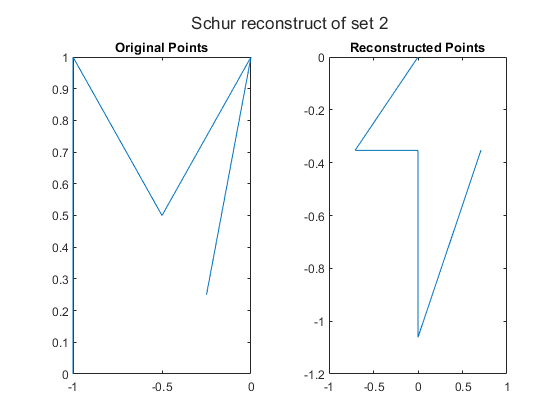

% The distance matrix of set 2
d = distance_matrix(set_2);
X = schur_reconstruct(d);

% Plots
figure;
t = tiledlayout(1,2);
title(t, "Schur reconstruct of set 2");

ax1 = nexttile;
plot(set_2(:,1), set_2(:, 2));
title(ax1,'Original Points');

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Reconstructed Points');

Result is plotted and shown side by side with its original For set 2, the data given is similar to set 1, the original location is formed as a M-shape with one twisted leg, however the Schur reconstruction returns a rotated and twisted M-shape that identical to the reconstructed shape in set 1 but in a opposite direction.

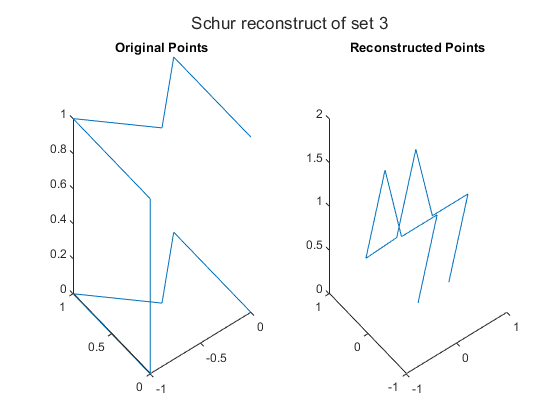

% The distance matrix of set 3
d = distance_matrix(set_3);
X = schur_reconstruct(d);

% Plots
figure;
t = tiledlayout(1,2);
title(t, "Schur reconstruct of set 3");

ax1 = nexttile;
plot3(set_3(:,1), set_3(:, 2), set_3(:,3));
title(ax1,'Original Points');

ax2 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax2,'Reconstructed Points');

Result is plotted and shown side by side with its original. For set 3, the data given is three-dimensional, the original location is formed as a shape that one M is identical to another in the different height but connected by one single line. However the Schur reconstruction returns a rotated shape that identical but shifted. 

**Reconstruct the Hilbert Curve using SVD method:**

SVD Reconstruction of 2D Hilbert Curve at 1,2,3 iterations 

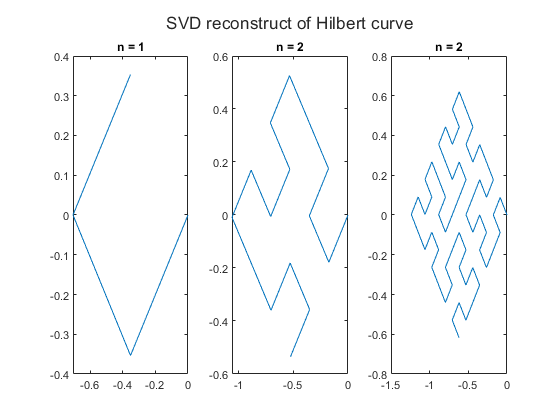

% Plots
figure;
t = tiledlayout(1,3);
title(t, "SVD reconstruct of Hilbert curve");

% Hilbert Curve n = 1
d = distance_matrix_hilbert(1, 2);
X = svd_reconstruct(d);

ax1 = nexttile;
plot(X(:,1), X(:, 2));
title(ax1,'n = 1');

% Hilbert Curve n = 2
d = distance_matrix_hilbert(2, 2);
X = svd_reconstruct(d);

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'n = 2');

% Hilbert Curve n = 3
d = distance_matrix_hilbert(3, 2);
X = svd_reconstruct(d);

ax3 = nexttile;
plot(X(:,1), X(:, 2));
title(ax3,'n = 2');

The plot of the largest singular value of the SVD routine for both Hilbert 2D and 3D is shown below.

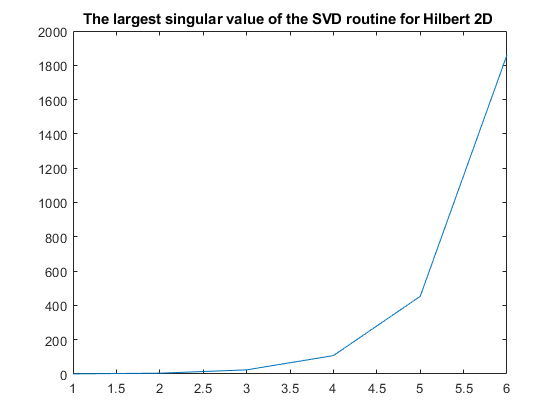

s_values = [];
iteration = 1:6;
for i = 1:length(iteration)
    d = distance_matrix_hilbert(i, 2);
    % Length of  distance matrix
    n = length(d);

    % Calculate M = X * transpose(X)
    % M = (m(i,j) for i,j = 1, ... n-1))
    M = zeros(n, n);

    % SVD method to reconstruct coordinates
    for i = 1:n
        for j = 1:n
            M(i, j) = (d(i, n) ^ 2 - d(i, j) ^ 2 + d(j, n) ^ 2)/2;
        end
    end

    s = svd(M);
   
    s_values = [s_values max(s)];
end

figure;
plot(iteration, s_values)
title("The largest singular value of the SVD routine for Hilbert 2D ");

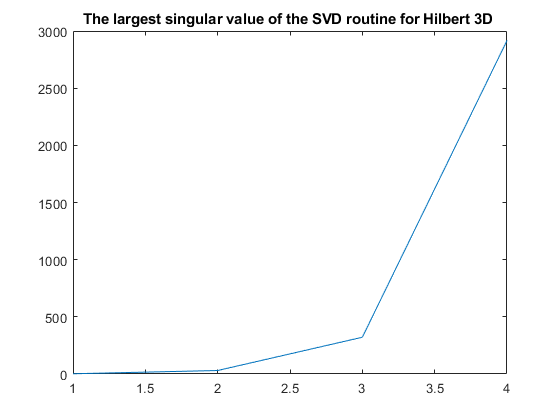


s_values = [];
iteration = 1:4;
for i = 1:length(iteration)
    d = distance_matrix_hilbert(i, 3);
    % Length of  distance matrix
    n = length(d);

    % Calculate M = X * transpose(X)
    % M = (m(i,j) for i,j = 1, ... n-1))
    M = zeros(n, n);

    % SVD method to reconstruct coordinates
    for i = 1:n
        for j = 1:n
            M(i, j) = (d(i, n) ^ 2 - d(i, j) ^ 2 + d(j, n) ^ 2)/2;
        end
    end

    s = svd(M);
   
    s_values = [s_values max(s)];
end

figure;
plot(iteration, s_values);
title("The largest singular value of the SVD routine for Hilbert 3D ");

LLS Build Up algorithm on three set of nodes

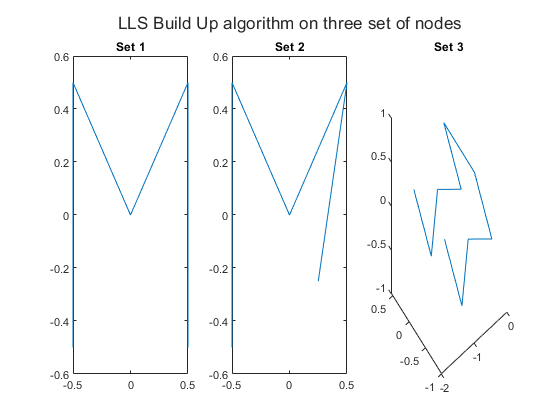

% Plots
figure;
t = tiledlayout(1,3);
title(t, "LLS Build Up algorithm on three set of nodes");

% Set 1
d = distance_matrix(set_1);
X = build_up_LLS(d, 2);

ax1 = nexttile;
plot(X(:,1), X(:, 2));
title(ax1,'Set 1');

% Set 2
d = distance_matrix(set_2);
X = build_up_LLS(d, 2);

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Set 2');

% Set 3
d = distance_matrix(set_3);
X = build_up_LLS(d, 3);

ax3 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax3,'Set 3');

Result is plotted for set 1 and set 2, which is in two-dimensional, the LLS Build Up shape is identical to its original. For set 3 which is in three-dimensional, the LLS Build Up shape is rotated that is identical to original but shrunk.

LLS Build Up algorithm is successfully computed on Hilbert 2D and 3D with n = 2, 3, 4

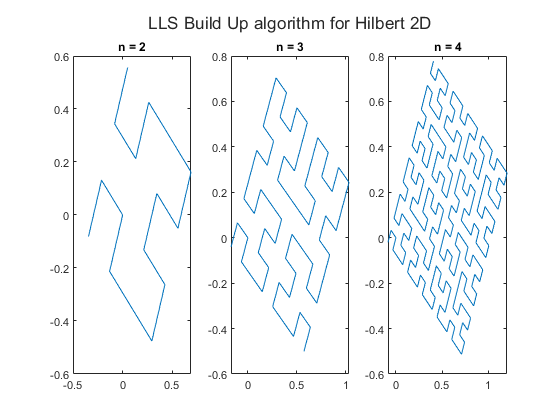

% Plots
figure;
t = tiledlayout(1,3);
title(t, "LLS Build Up algorithm for Hilbert 2D");

% 2D with n = 2
d = distance_matrix_hilbert(2, 2);
X = build_up_LLS(d, 2);

ax1 = nexttile;
plot(X(:,1), X(:, 2));
title(ax1,'n = 2');

% 2D with n = 3
d = distance_matrix_hilbert(3, 2);
X = build_up_LLS(d, 2);

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'n = 3');

% 2D with n = 4
d = distance_matrix_hilbert(4, 2);
X = build_up_LLS(d, 2);

ax3 = nexttile;
plot(X(:,1), X(:, 2));
title(ax3,'n = 4');

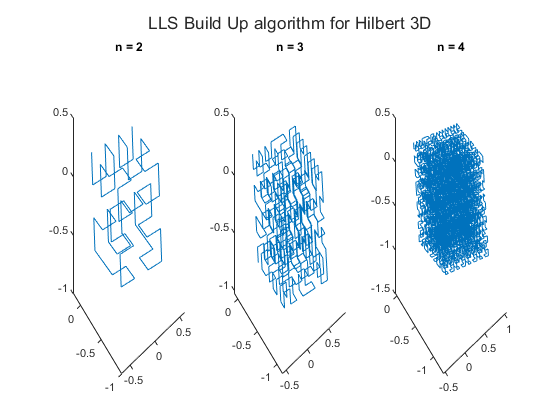

% Plots
figure;
t = tiledlayout(1,3);
title(t, "LLS Build Up algorithm for Hilbert 3D");

% 3D with n = 2
d = distance_matrix_hilbert(2, 3);
X = build_up_LLS(d, 3);

ax1 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax1,'n = 2');

% 3D with n = 3
d = distance_matrix_hilbert(3, 3);
X = build_up_LLS(d, 3);

ax2 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax2,'n = 3');

% 3D with n = 4
d = distance_matrix_hilbert(4, 3);
X = build_up_LLS(d, 3);

ax3 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax3,'n = 4');

In the computing process, there is an obvious difference between LLS and SVD for Hilbert 2D and 3D. The LLS performs better perfomance since it only implements SVD to calculate the first k + 1 points. Then it computes the undetermined points consecutively . Meanwhile, the SVD method calculates the sets of coordinates as a whole. In ideal circumstances, the LLS technique could solve a distance geometry issue in O(n) computation time using 4n distances, whereas the traditional singular value decomposition technique requires all n(n-1)/2 distances and O(n^2) computing time, where n is the number of points to be determined.

#### LLS Build Up Algorithm for Distance matrix with noise

For the 2D and 3D Hilbert curve, distance matrix is computed (see code distance_matrix_hilbert.m) and noise is added successfully (see code distance_matrix_wNoise.m), the maximum norm of distance is found (see code find_max_norm.m ), the maximum norm of the distance that the nodes shift from no-noise is plotted and shown below

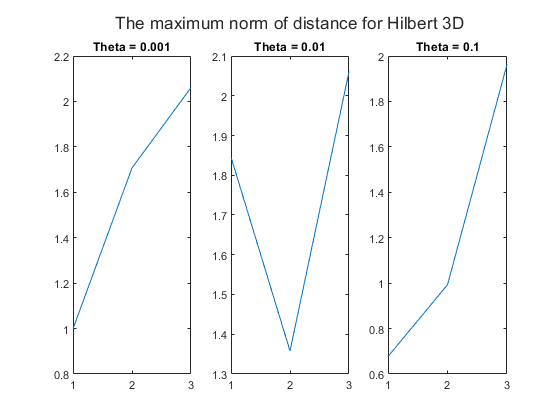

theta = [0.001 0.01 0.1];
n = 1:3;
dim = 3;
max_norm = zeros(1, length(n));



figure;
t = tiledlayout(1,3);
title(t, "The maximum norm of distance for Hilbert 3D");

for j = 1:length(theta)
    for i = 1:length(n)
        d = distance_matrix_hilbert(i, dim);
        d_noise = distance_matrix_wNoise(d, theta(j)); % Add noise
        
        % Reconstruct with LLS
        X = build_up_LLS(d, dim);
        X_noise = build_up_LLS(d_noise, dim);
        
        max_norm(i) = find_max_norm(X, X_noise);
    end
    
    ax1 = nexttile;
    plot(n, max_norm);
    title(ax1, strcat("Theta = ", num2str(theta(j))));
end

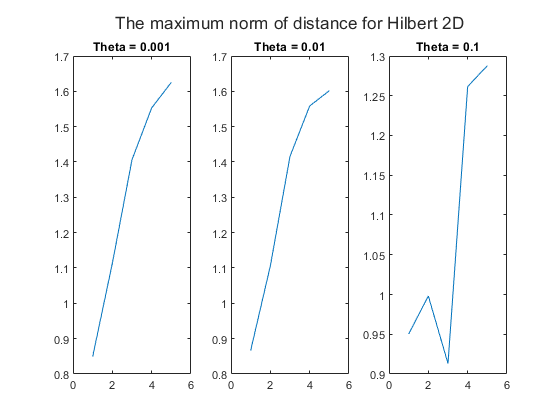

theta = [0.001 0.01 0.1];
n = 1:5;
dim = 2;
max_norm = zeros(1, length(n));

figure;
t = tiledlayout(1,3);
title(t, "The maximum norm of distance for Hilbert 2D");

for j = 1:length(theta)
    for i = 1:length(n)
        d = distance_matrix_hilbert(i, dim);
        d_noise = distance_matrix_wNoise(d, theta(j)); % Add noise
        
         % Reconstruct with LLS
        X = build_up_LLS(d, dim);
        X_noise = build_up_LLS(d_noise, dim);
        
        max_norm(i) = find_max_norm(X, X_noise);
    end
    
    ax1 = nexttile;
    plot(n, max_norm);
    title(ax1, strcat("Theta = ", num2str(theta(j))));
end

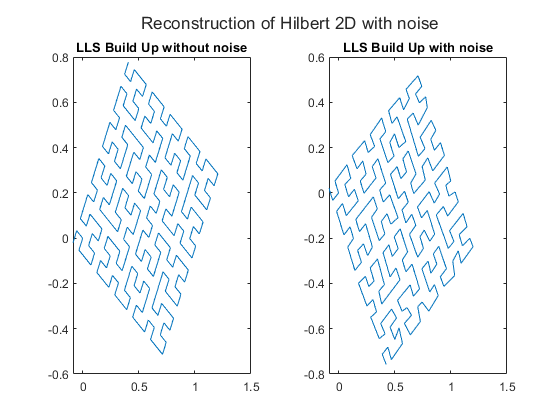

d = distance_matrix_hilbert(4, 2);
d_noise = distance_matrix_wNoise(d, theta(2)); % Add noise

% Reconstruct with LLS
X = build_up_LLS(d, 2);
X_noise = build_up_LLS(d_noise, 2);

figure;
t = tiledlayout(1,2);
title(t, "Reconstruction of Hilbert 2D with noise");

ax1 = nexttile;
plot(X(:,1), X(:, 2));
title(ax1, "LLS Build Up without noise");

ax1 = nexttile;
plot(X_noise(:,1), X_noise(:, 2));
title(ax1, "LLS Build Up with noise");

## Discussion

Space-filling curve has been important in many aspect of computation, some finding and application has found in the result. In the process of finding solution, some opinions and point of view has been anticipated. 

Hilbert curve is the most common and practical curve in space-filling curve world, however it has strengths and limitations. Hilbert curve is widely accessible (even for people who has less understanding of writing algorithm),  and research of its application and usage are well explored, it is published in many papers of different aspects. Moreover, Hilbert curve is computational affordable, it can be computed by most computer in a brief time period. Furthermore, due to its accessibility and simplicity, it requires additional modification for special needs, for example, sketching, transforming or rotating.

SVD is a frequent tool for factorization of complex matrix, it is powerful for compression and de-noising, as it only extract a small set of singular value and vector to represent the matrix set. Nevertheless, SVD also has limitations, as the finding in the result shown, SVD reconstruction of Hilbert curve appears to be slightly twisted and rotated although the functionality of Hilbert curve doesn't change. Correspondingly, Schur reconstruction of Hilbert curve produces related pattern with persisting functionality. 

LLS build up algorithm is devised as an efficient approach that has improvement on running time. The concept behind the method is to first determine a small group of points and then finish the set by repeatedly determining one or more points utilizing the available distances between the determined and undetermined points. The advantage of employing a geometric buildup technique is that it works directly on the provided distances, potentially solving the problem faster than a general technique.

## Reference

- Sit, Atilla, "**Solving distance geometry problems for protein structure determination**" (2010). Graduate Theses and Dissertations. 11275